smatalb = settings;
smatalb.matlab.appearance.figure.GraphicsTheme.TemporaryValue= 'light'; % Can be set to auto (default), light, or dark
clear variables;
clc;
close all;
load robotarmdata.mat;

### Exame the whole data set 

z = iddata({ye yv1 yv2 yv3}, {ue uv1 uv2 uv3}, 0.5e-3, 'Name', 'Robot arm');
z.InputName = 'Applied motor torque';
z.InputUnit = 'Nm';
z.OutputName = 'Angular velocity of motor';
z.OutputUnit = 'rad/s';
z.ExperimentName = {'Estimation' 'Validation 1'  'Validation 2' 'Validation 3'};
z.Tstart = 0;
z.TimeUnit = 's';
present(z);

th = Time domain data set containing 4 experiments.
         
Experiment                      Samples      Sample Time
   Estimation                    19838            0.0005
   Validation 1                  19838            0.0005
   Validation 2                  19838            0.0005
   Validation 3                  19838            0.0005
                                                        
Name: Robot arm                                         
                                                        
Outputs                         Unit (if specified)     
   Angular velocity of motor       rad/s                
                                                        
Inputs                          Unit (if specified)     
   Applied motor torque            Nm                   
                                                        


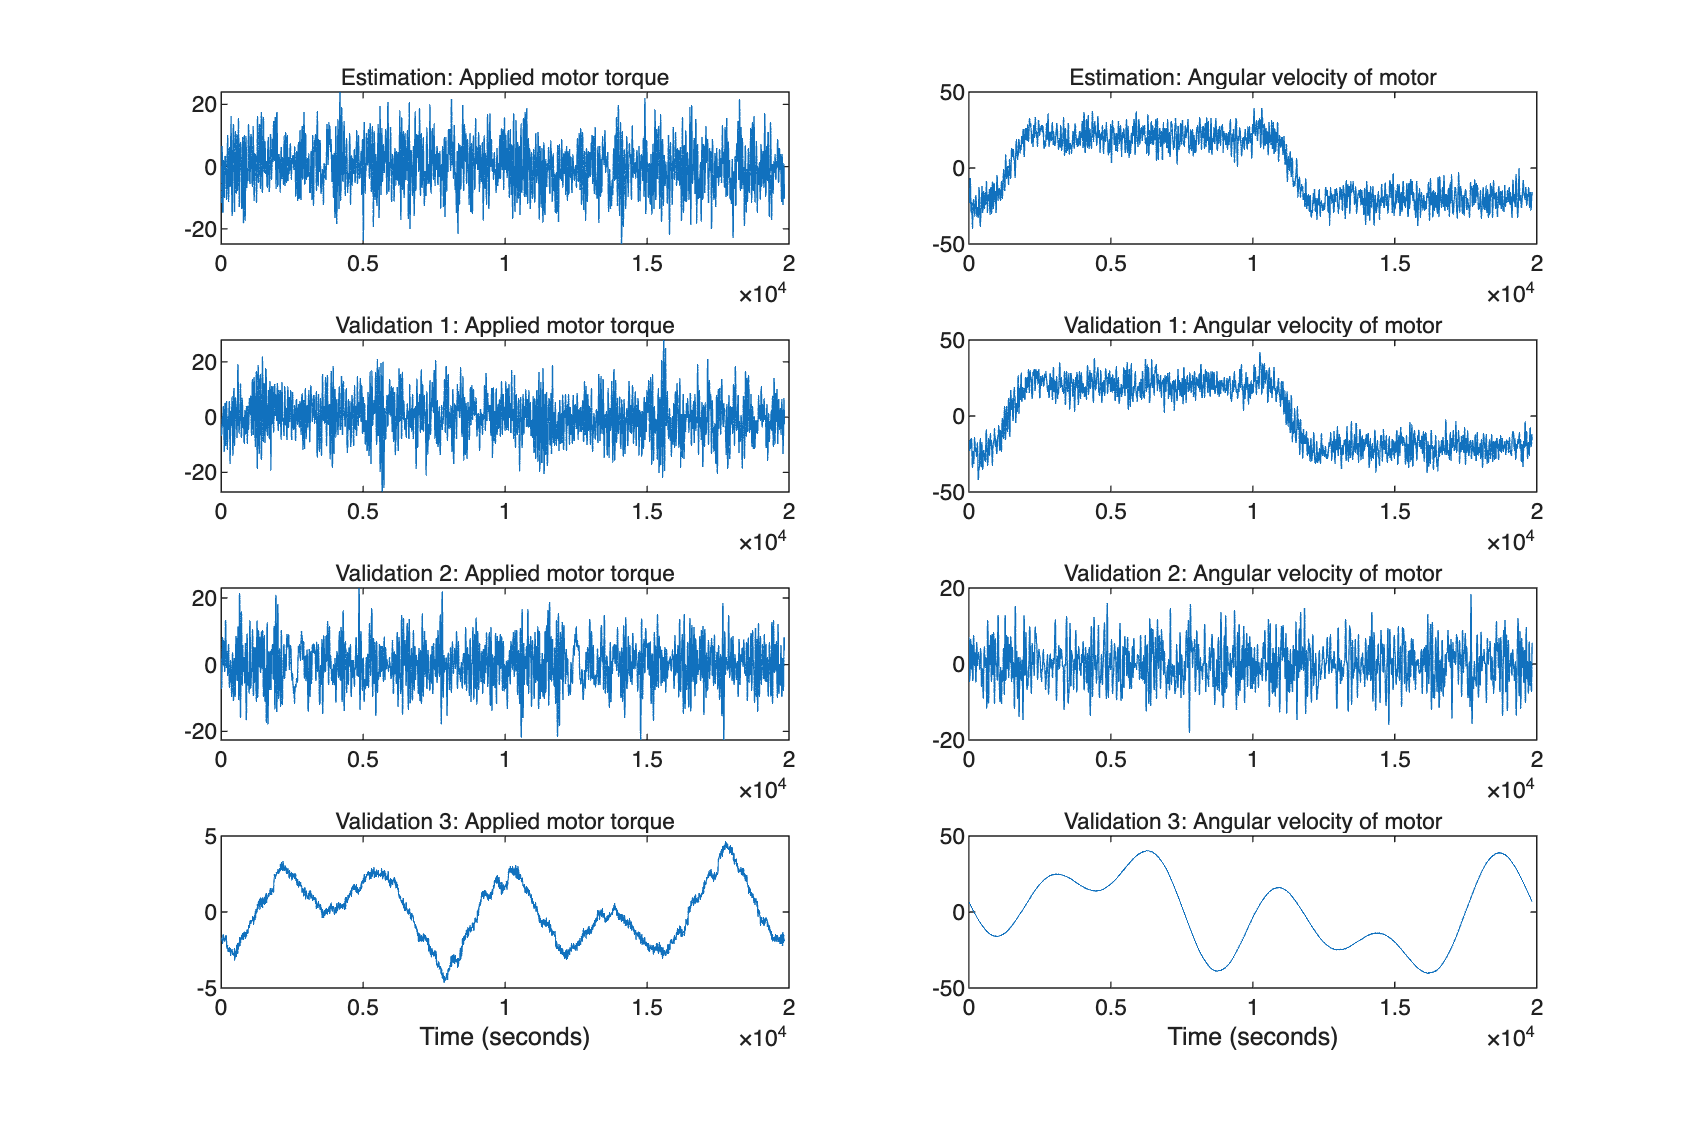


figure('Name', [z.Name ': input-output data'],...
   'DefaultAxesTitleFontSizeMultiplier',1,...
   'DefaultAxesTitleFontWeight','normal',...
   'Position',[100 100 900 600]);
ne = size(z,'ne');
for i = 1:ne
    zi = getexp(z, i);
    subplot(ne, 2, 2*i-1);   % Input.
    plot(zi.u);
    title([z.ExperimentName{i} ': ' zi.InputName{1}],'FontWeight','normal');
    if (i < ne)
        xlabel('');
    else
        xlabel([z.Domain ' (' zi.TimeUnit ')']);
    end
    subplot(ne, 2, 2*i);     % Output.
    plot(zi.y);
    title([z.ExperimentName{i} ': ' zi.OutputName{1}],'FontWeight','normal');
    if (i < ne)
        xlabel('');
    else
        xlabel([z.Domain ' (' zi.TimeUnit ')']);
    end
end

dta_all = idresamp(z,[1 10]);
present(dta_all);

th = Time domain data set containing 4 experiments.
         
Experiment                      Samples      Sample Time
   Estimation                     1984            0.005 
   Validation 1                   1984            0.005 
   Validation 2                   1984            0.005 
   Validation 3                   1984            0.005 
                                                        
Name: Robot arm                                         
                                                        
Outputs                         Unit (if specified)     
   Angular velocity of motor       rad/s                
                                                        
Inputs                          Unit (if specified)     
   Applied motor torque            Nm                   
                                                        


dta_train = getexp(dta_all, 1);
present(dta_train);

th = Time domain data set with 1984 samples.            
Sample time: 0.005 seconds                         
Name: Robot arm                                    
                                                   
Outputs                         Unit (if specified)
   Angular velocity of motor       rad/s           
                                                   
Inputs                          Unit (if specified)
   Applied motor torque            Nm              
                                                   
Data Properties

### Decide u y scaling 

dqmax = zeros(4,1);
dqmax(1) = max(abs(dta_all.OutputData{1}), [], "all");
dqmax(2) =  max(abs(dta_all.OutputData{2}), [], "all");
dqmax(3) =  max(abs(dta_all.OutputData{3}), [], "all");
dqmax(4) =  max(abs(dta_all.OutputData{4}), [], "all");
dqmax

dqmax =    39.0250
   41.2380
   17.7049
   40.3775


umax = zeros(4,1);
umax(1) = max(abs(dta_all.InputData{1}), [], "all");
umax(2) =  max(abs(dta_all.InputData{2}), [], "all");
umax(3) =  max(abs(dta_all.InputData{3}), [], "all");
umax(4) =  max(abs(dta_all.InputData{4}), [], "all");
umax

umax =    24.2009
   24.2159
   22.6076
    4.5867


dq_scale = 1.1 * max(dqmax, [], 'all');  

dq_scale = max(dq_scale, 1e-8);
disp("dq_scale = " + dq_scale);

dq_scale = 45.3618


u_scale= 1.1 * max(umax, [], 'all');
u_scale = max(u_scale, 1e-8);
disp("u_scale = " + u_scale);

u_scale = 26.6375


### Create data

N_whole = length(dta_all.InputData{1})

N_whole = 1984

nBatch = 4;
p7_dim = 7;
p7 = zeros(N_whole, p7_dim, nBatch);
u_log_mat  = zeros(N_whole, nBatch);
u_log_mat(:,1) = dta_all.InputData{1};
u_log_mat(:,2) = dta_all.InputData{2};
u_log_mat(:,3) = dta_all.InputData{3};
u_log_mat(:,4) = dta_all.InputData{4};


y_log_mat = zeros(N_whole, nBatch);
y_log_mat(:,1) = dta_all.OutputData{1};
y_log_mat(:,2) = dta_all.OutputData{2};
y_log_mat(:,3) = dta_all.OutputData{3};
y_log_mat(:,4) = dta_all.OutputData{4};

tanh_dq1_log_mat = tanh(y_log_mat);

% One step Delay function declare 
delay1 = @(x) [0; x(1:end-1)];
zero_mat = zeros(N_whole, nBatch);

for k = 1:nBatch
    p7(:,:,k) = [u_log_mat(:,k), ...
                  delay1(y_log_mat(:,k)), ...
                  zero_mat(:,k), ...
                  zero_mat(:,k), ...
                  zero_mat(:,k), ...
                  zero_mat(:,k), ...
                  delay1(tanh_dq1_log_mat(:,k))];
end


%% Quick sanity checks
disp('Last 3 rows: opt_train_mat vs opt_train_delay_mat (should be shifted by 1)');

Last 3 rows: opt_train_mat vs opt_train_delay_mat (should be shifted by 1)


disp(y_log_mat(end-2:end, :));

  -26.7305  -19.2488   -4.9140    8.0286
  -22.5118  -18.7407   -7.2056    7.6629
  -17.8847  -14.5204   -3.6416    7.5091



disp( p7(end-2:end, 2,:));


(:,:,1) =

  -25.8315
  -26.7305
  -22.5118


(:,:,2) =

  -18.7741
  -19.2488
  -18.7407


(:,:,3) =

   -0.7637
   -4.9140
   -7.2056


(:,:,4) =

    8.6719
    8.0286
    7.6629



p7 = permute(p7, [2 1 3]);   % now rho_dim x N x nBatch


Get data for all batches no chop

dta1 = struct();
dta1.ipt_train_mat = reshape(u_log_mat, [1 size(u_log_mat)]);
dta1.opt_train_mat = reshape(y_log_mat, [1 size(y_log_mat)]);
dta1.p_train_delay_mat = p7;
dta1.N_train = N_whole;
dta1.n_train = nBatch;
dta1.u_scale = u_scale;
dta1.dq_scale = dq_scale;

Export data

dta = dta1;
save('Data_arm_nochop_v4','dta');